# Opgave 1: Gram-Schmidt

#### Oefening 3

m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0063   -0.0119   -0.0235   -0.0001   -0.0082   -0.0079   -0.0063   -0.0075   -0.0065   -0.0062   -0.0064   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063
   -0.1050   -0.1102   -0.1303   -0.1166   -0.1102   -0.1042   -0.1064   -0.1056   -0.1050   -0.1050   -0.1051   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0.1050   -0

#### Oefening 4

e1 = zeros(n, 1);
e2 = zeros(n, 1);

[Q1,~] = klGS(A)

Q1 =    -0.0063   -0.0111   -0.0687    0.0494   -0.0298   -0.0500   -0.0001   -0.1532   -0.0491    0.0429   -0.0646    0.0239    0.0502    0.0116    0.1115    0.0367    0.1226   -0.0611   -0.0462    0.0440   -0.0516    0.0173    0.0136   -0.0604    0.0448   -0.0753    0.1292   -0.0308   -0.0088   -0.0525   -0.1424   -0.0429    0.0432    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431    0.0431
   -0.1050   -0.0105   -0.1014   -0.0931   -0.0830    0.0256   -0.0883   -0.0764    0.0020    0.0121   -0.0734   -0.0010    0.0051   -0.0525   -0.0771   -0.0033   -0.0091   -0.0681   -0.0359   -0.0760   -0.0046   -0.0652   -0.0764    0.0595   -0.0367   -0.0287    0.0322    0.0389    0.1126   -0.0476   -0.0351   -0.0209    0.0207    0.0209    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    

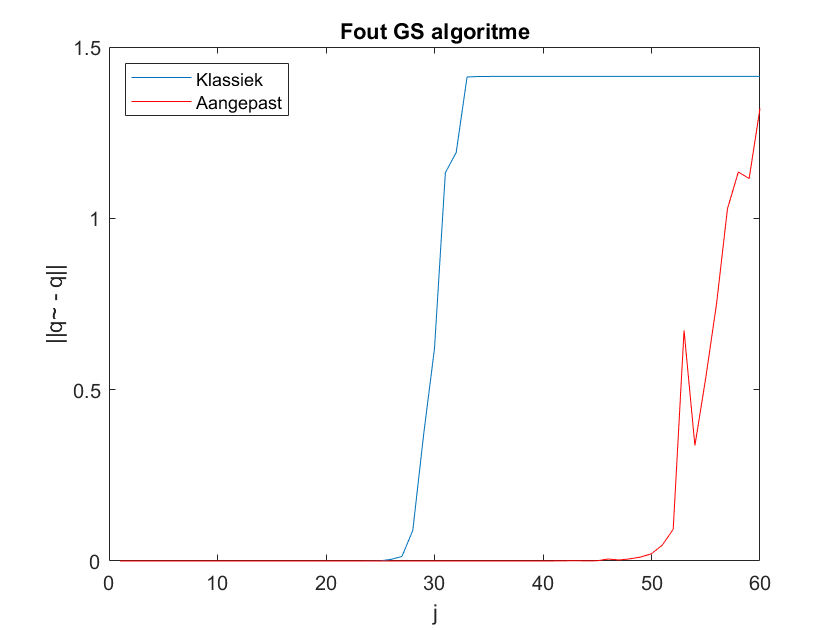

[Q2,~] = modGS(A);

for j = 1:n
    e1(j, 1) = norm(Q1(:,j)-Q(:,j));
    e2(j, 1) = norm(Q2(:,j)-Q(:,j));
end

% linear scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')

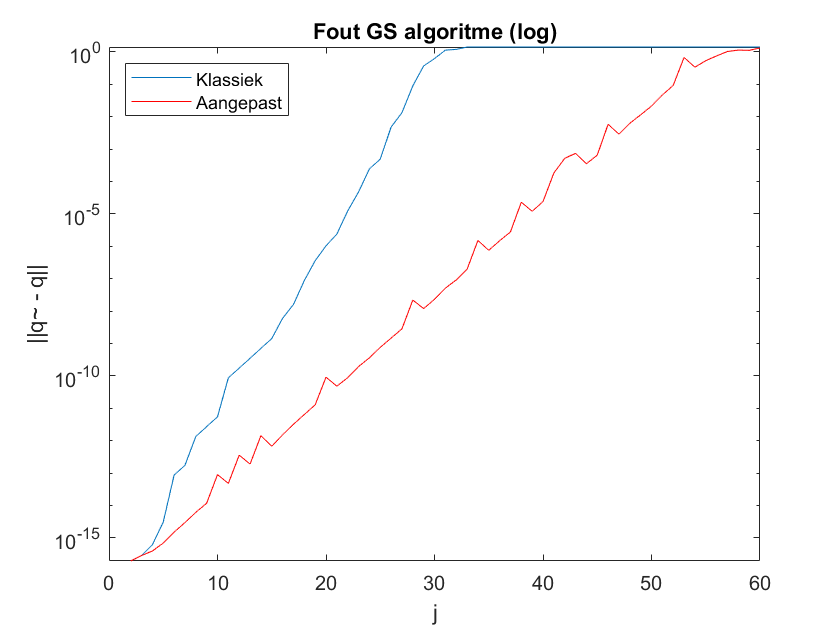


% logarithmic scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme (log)")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')
set(gca, 'YScale', 'log')

#### Oefening 8

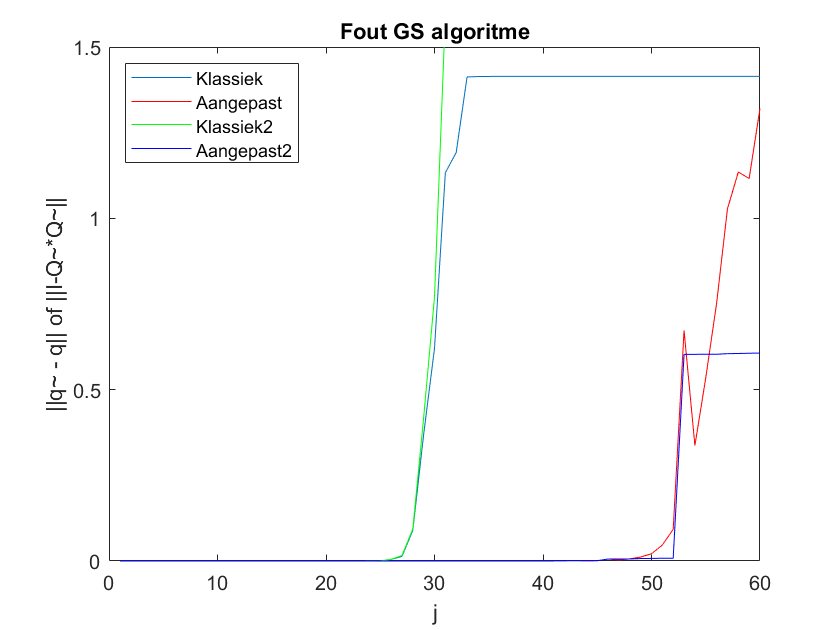

orth1 = zeros(n, 1);
orth2 = zeros(n, 1);

for j = 1:n
    orth1(j, 1) = norm(eye(j) - Q1(:,1:j)'*Q1(:,1:j));
    orth2(j, 1) = norm(eye(j) - Q2(:,1:j)'*Q2(:,1:j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold on
plot(orth1, 'Color', 'g')
hold on
plot(orth2,'Color','b')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q|| of ||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Klassiek2', 'Aangepast2', 'Location','northwest')
axis([0 60 0 1.5])

#### Oefening 5

m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0953   -0.0701   -0.0918
   -0.0239   -0.0625   -0.0402
    0.0608    0.0863    0.0521
   -0.0658   -0.0347   -0.0775
    0.0238   -0.0030    0.0088
    0.0228   -0.0221    0.0391
   -0.0795   -0.1019   -0.0676
   -0.1035   -0.0782   -0.1402
    0.0472    0.0508    0.0319
    0.1142    0.1027    0.1146


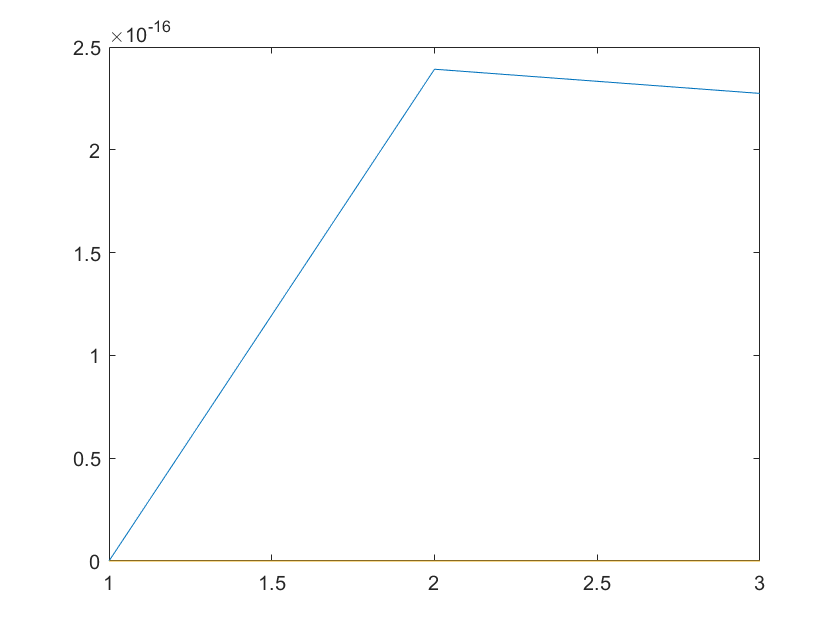


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

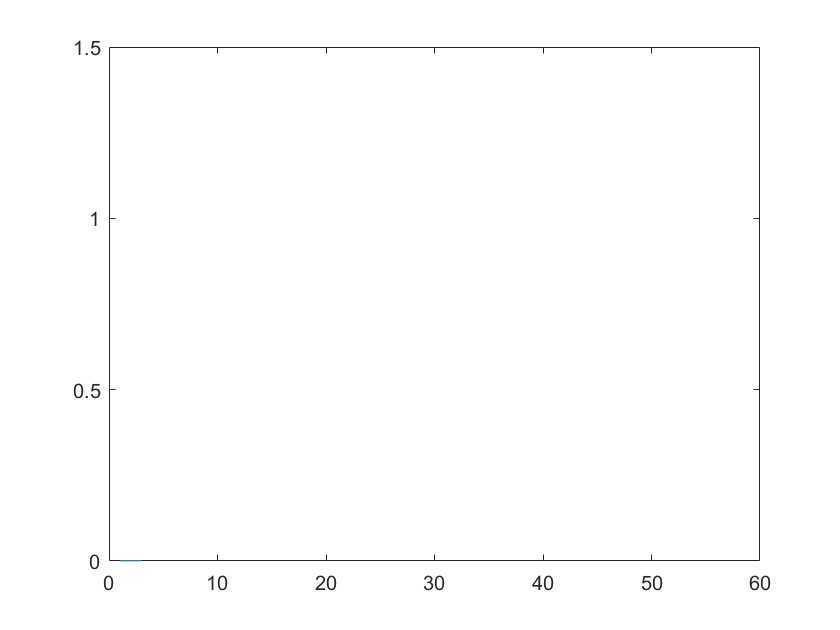


% comparison of theoretical error (te) with experimental error (e)
te1 = zeros(n);
te2 = zeros(n);
x = zeros(1,n);
for j = 1:n
    x(j) = 2^(j-1);
    te1(j) = 2^(j-1)*norm(x)*eps;
    te2(j) = 2^(j-1)*eps;
end
plot(te1)
hold on
plot(te2)
hold off
axis([0 60 0 1.5])

#### Oefening 9

m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

[V,~] = qr(rand(n));
V = 10*rand*V;

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A;

K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


#### Oefening 10

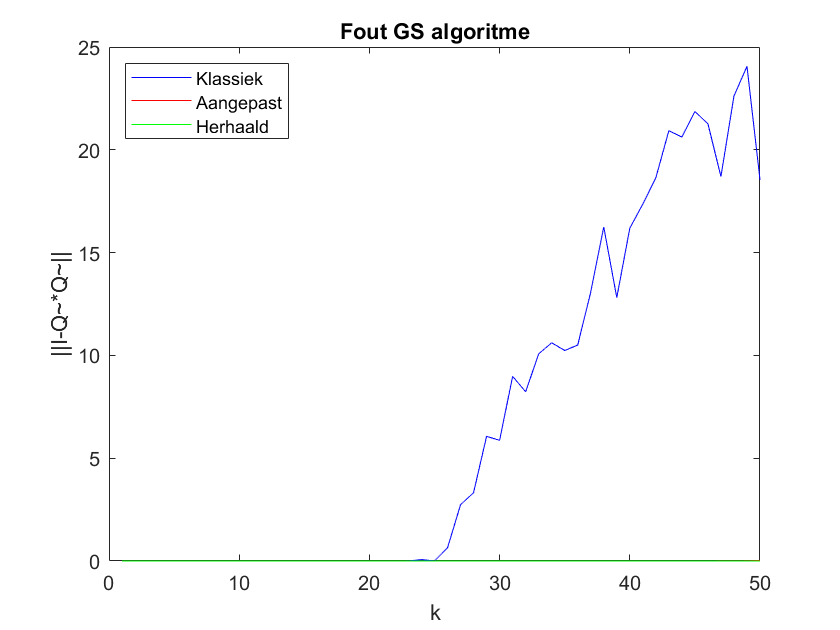

Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1;

Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2;

Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3;

orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1;

orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2;

orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3;

plot(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

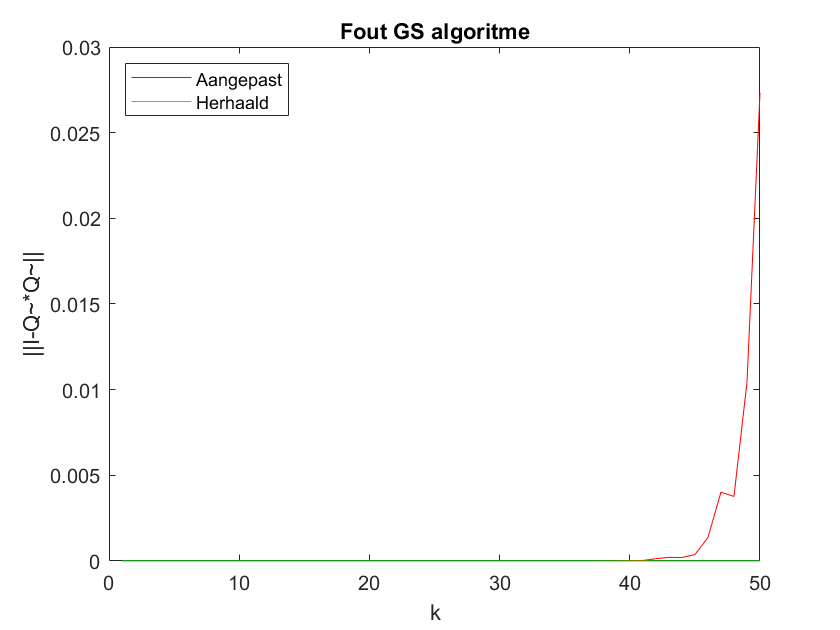

plot(k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Aangepast', 'Herhaald', 'Location','northwest')

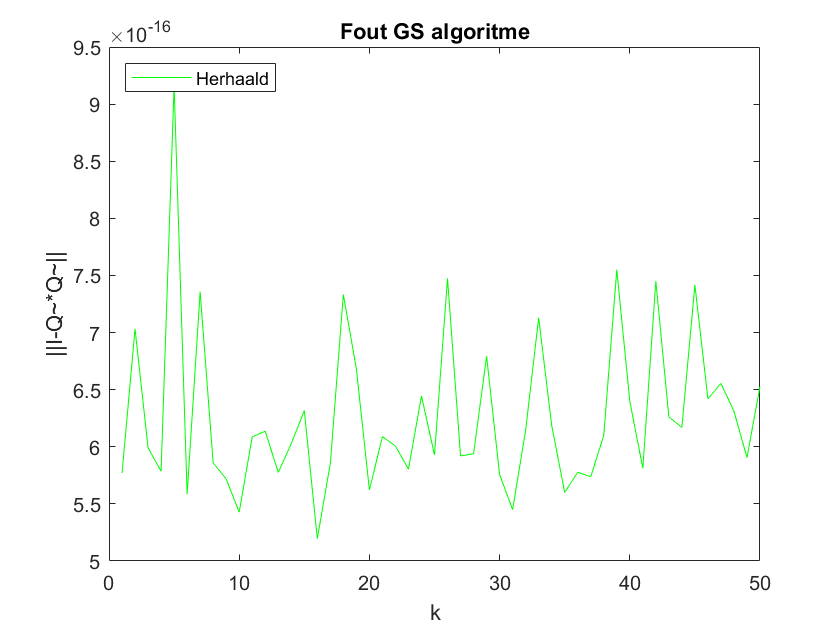

plot(k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Herhaald', 'Location','northwest')


rorth1 = zeros(50, 1);
rorth2 = zeros(50, 1);
rorth3 = zeros(50, 1);
for i=k
    rorth1(i) = log( (orth1(i)) /( 2^(-52) ) ) /log(K(i));
    rorth2(i) = log( (orth2(i)) /( 2^(-52) ) ) /log(K(i));
    rorth3(i) = log( (orth3(i)) /( 2^(-52) ) ) /log(K(i));
end
rorth1

rorth1 =     1.3666
    0.8604
    0.8785
    0.9229
    1.1020
    1.1355
    1.2840
    1.2679
    1.3092
    1.3871


rorth2

rorth2 =     1.5418
    0.7787
    0.6229
    0.5991
    0.6644
    0.5919
    0.7008
    0.6799
    0.7146
    0.7582


rorth3

rorth3 =     1.3777
    0.8314
    0.4774
    0.3454
    0.4091
    0.2218
    0.2469
    0.1750
    0.1516
    0.1290


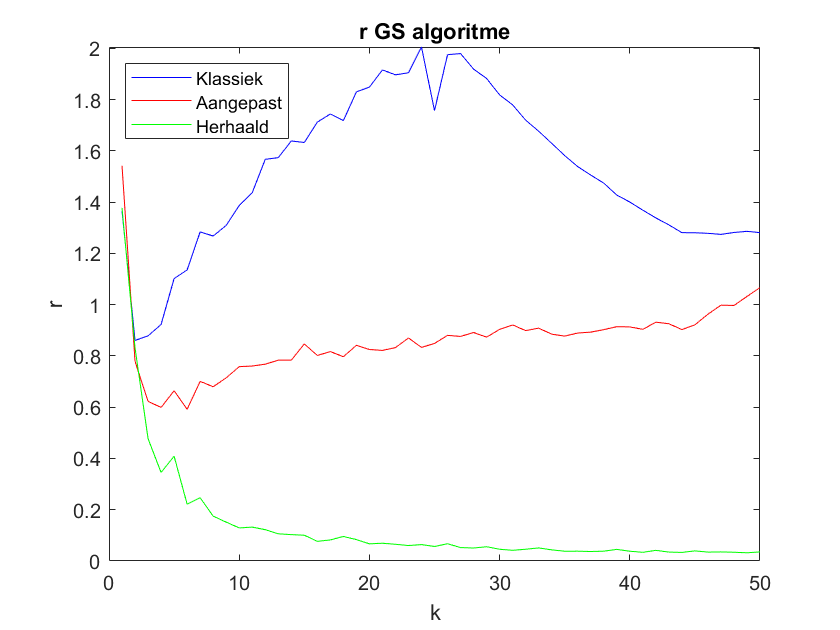


plot(k, rorth1, 'b', k, rorth2, 'r', k, rorth3, 'g')
hold off
title("r GS algoritme")
xlabel('k')
ylabel('r')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000, 100);
n = length(A);
m = 100;
v = rand(n,1);

ritzvaluesiterations = zeros(m, 6);
for i=1:m
    [V,H] = Arnoldi(A,v,i);
    Hn = H(1:i, :);
    [~, ritzvalues] = eigs(Hn);
    for k=1:length(ritzvalues)
        ritzvaluesiterations(i, k) = ritzvalues(k, k);
    end
end

[V,H] = Arnoldi(A,v,m);

colors = ['g', 'b', 'c', 'r', 'm', 'y']

colors = 'gbcrmy'

eigenvalues = zeros(6, 1);
[~, eigenvaluesdiagonal] = eigs(A);
for eigenvalue=1:6
    eigenvalues(eigenvalue) = eigenvaluesdiagonal(eigenvalue, eigenvalue);
    plot(real(eigenvalues(eigenvalue)), imag(eigenvalues(eigenvalue)), 'x', "MarkerSize",20, "Color", colors(eigenvalue))
    hold on
end

eigenvalues

eigenvalues = 	1.0e+02 *

   3.1614 + 0.0000i
  -0.0211 + 0.1063i
  -0.0211 - 0.1063i
   0.0197 + 0.1054i
   0.0197 - 0.1054i
   0.0393 + 0.0992i


ritzvaluesiterations;
Hn = H(1:m, :);
[~, ritzvalues] = eigs(Hn);

ritz1 = ritzvaluesiterations(:, 1)

ritz1 =   235.8545
  316.0310
  316.1358
  316.1361
  316.1361
  316.1361
  316.1361
  316.1361
  316.1361
  316.1361


ritz2 = ritzvaluesiterations(:, 2)

ritz2 =    0.0000 + 0.0000i
  -0.6109 + 0.0000i
  -1.8082 + 0.0000i
   2.2914 + 0.0000i
  -3.9418 + 4.2232i
   4.4746 + 3.4838i
  -7.0443 + 0.0000i
   5.0228 + 4.6800i
  -3.0825 + 6.7434i
   6.8947 + 4.2624i


ritz3 = ritzvaluesiterations(:, 3)

ritz3 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.3504 + 0.0000i
  -1.4340 + 0.7562i
  -3.9418 - 4.2232i
   4.4746 - 3.4838i
  -3.4166 + 5.6626i
   5.0228 - 4.6800i
  -3.0825 - 6.7434i
   6.8947 - 4.2624i


ritz4 = ritzvaluesiterations(:, 4)

ritz4 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.4340 - 0.7562i
   3.6128 + 3.1574i
  -3.4449 + 4.0297i
  -3.4166 - 5.6626i
  -2.3138 + 5.8032i
   6.6125 + 3.1368i
  -7.3475 + 2.7147i


ritz5 = ritzvaluesiterations(:, 5)

ritz5 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.6128 - 3.1574i
  -3.4449 - 4.0297i
   4.7512 + 4.5650i
  -2.3138 - 5.8032i
   6.6125 - 3.1368i
  -7.3475 - 2.7147i


ritz6 = ritzvaluesiterations(:, 6)

ritz6 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.0741 + 0.0000i
   4.7512 - 4.5650i
  -5.3004 + 1.7616i
  -6.7069 + 2.3234i
  -3.4101 + 6.6607i


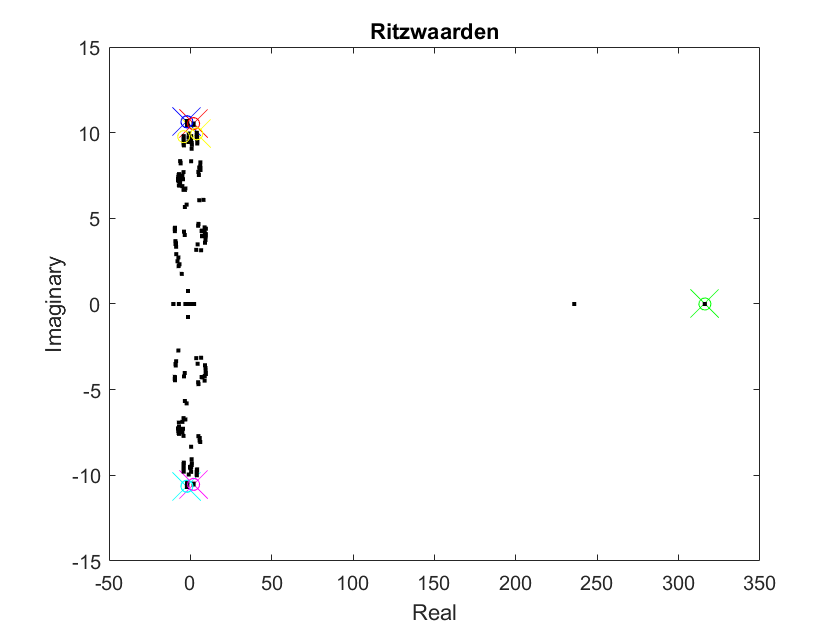

for k=1:100
    if k < 91
        plot(real(ritz1(k)), imag(ritz1(k)), '.', 'Color', 'k')
        plot(real(ritz2(k)), imag(ritz2(k)), '.', 'Color', 'k')
        plot(real(ritz3(k)), imag(ritz3(k)), '.', 'Color', 'k')
        plot(real(ritz4(k)), imag(ritz4(k)), '.', 'Color', 'k')
        plot(real(ritz5(k)), imag(ritz5(k)), '.', 'Color', 'k')
        plot(real(ritz6(k)), imag(ritz6(k)), '.', 'Color', 'k')
    end
    if k >= 91
        plot(real(ritz1(k)), imag(ritz1(k)), 'o', 'Color', colors(1))
        plot(real(ritz2(k)), imag(ritz2(k)), 'o', 'Color', colors(2))
        plot(real(ritz3(k)), imag(ritz3(k)), 'o', 'Color', colors(3))
        plot(real(ritz4(k)), imag(ritz4(k)), 'o', 'Color', colors(4))
        plot(real(ritz5(k)), imag(ritz5(k)), 'o', 'Color', colors(5))
        plot(real(ritz6(k)), imag(ritz6(k)), 'o', 'Color', colors(6))
    end
    pause(0.1)
end

hold off
title("Ritzwaarden")
xlabel('Real')
ylabel('Imaginary')